%This code classifies the data by using 104 Features.
%The code consists of confusion matrices and other performance metrices.
clear;
clc;
close all;

load dataset.mat

%Performance Metrices.
accuracy=[ ];
precision= [ ];
recall=[ ];
f1= [ ];

%Load the Dataset features and Targets.
x=data(:,1:104);
y=data(:,105);
classes=data(1:330,105);

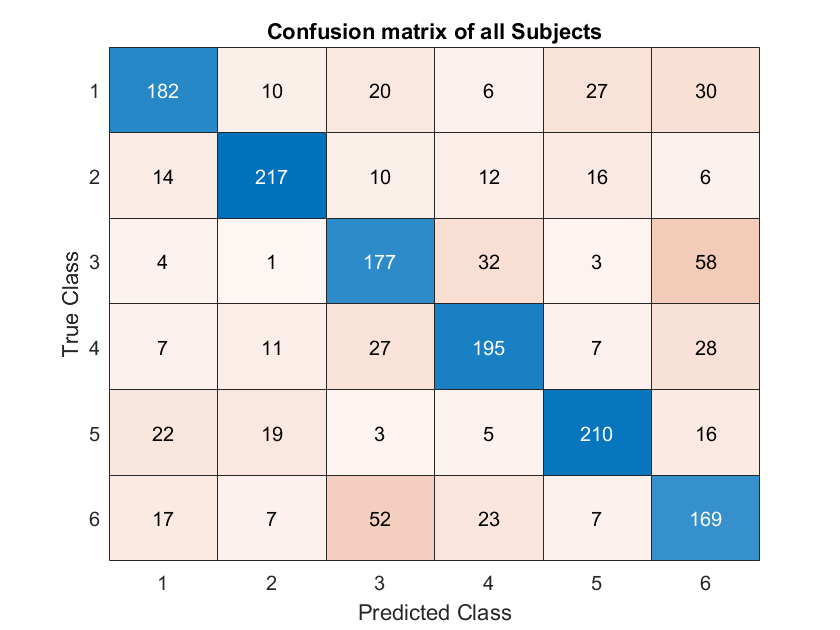

%Classifying all subject's data.
y_pred=sub_all(x);
confusion=confusionmat(y,vec2ind(y_pred'));

%Performance Metrices.
accuracy(6)=Accuracy(confusion);
precision(6,:)=Precision(confusion);
recall(6,:)=Recall(confusion);
f1(6,:)=F1_Score(precision(6,:),recall(6,:));

%Confusion Matrix.
figure;
confusionchart(y,vec2ind(y_pred'));
title('Confusion matrix of all Subjects');

%Retreiving single subject dataset.
%Calculating their accuracy and Confusion Matrix.
%F1 score, Specificity, Precision and Recall.
%Plotting the ROC curves.

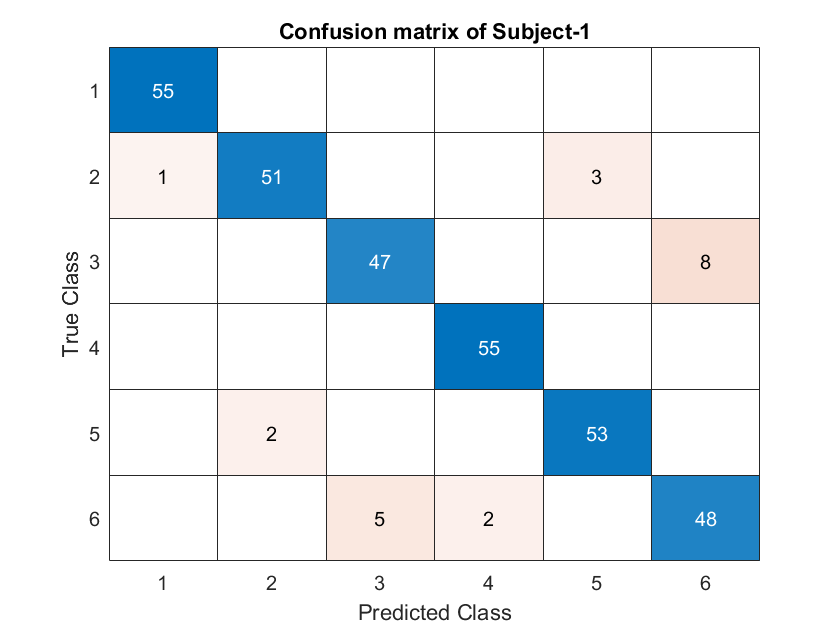

%Subject-1.
x=data(1:330,1:104);
y_pred=subject_104_1(x);
confusion=confusionmat(classes,vec2ind(y_pred'));

%Performance Metrices.
accuracy(1)=Accuracy(confusion);
precision(1,:)=Precision(confusion);
recall(1,:)=Recall(confusion);
f1(1,:)=F1_Score(precision(1,:),recall(1,:));

%Confusion Matrix.
figure;
confusionchart(classes,vec2ind(y_pred'));
title('Confusion matrix of Subject-1');

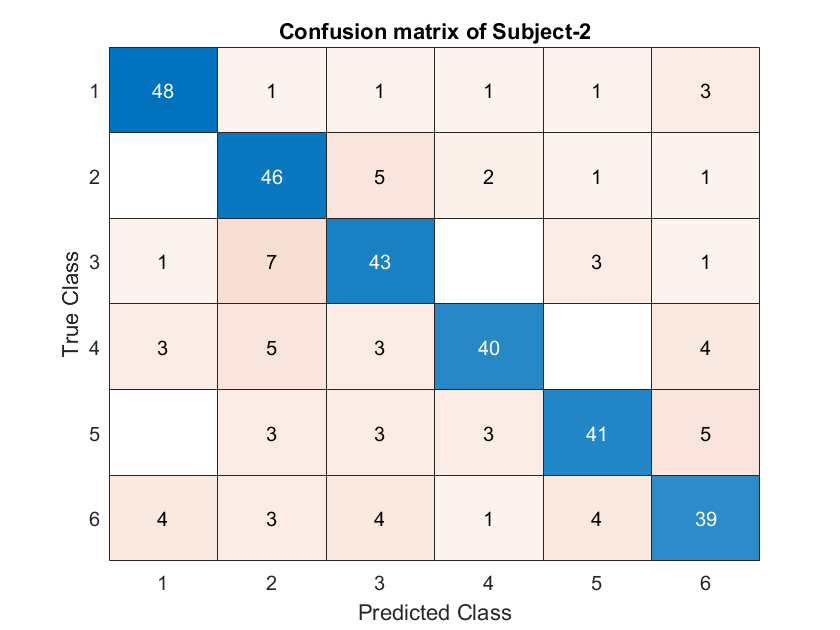

%Subject-2.
x=data(331:660,1:104);
y_pred=subject_104_2(x);
confusion=confusionmat(classes,vec2ind(y_pred'));

%Performance Metrices.
accuracy(2)=Accuracy(confusion);
precision(2,:)=Precision(confusion);
recall(2,:)=Recall(confusion);
f1(2,:)=F1_Score(precision(2,:),recall(2,:));

%Confusion Matrix.
figure;
confusionchart(classes,vec2ind(y_pred'));
title('Confusion matrix of Subject-2');

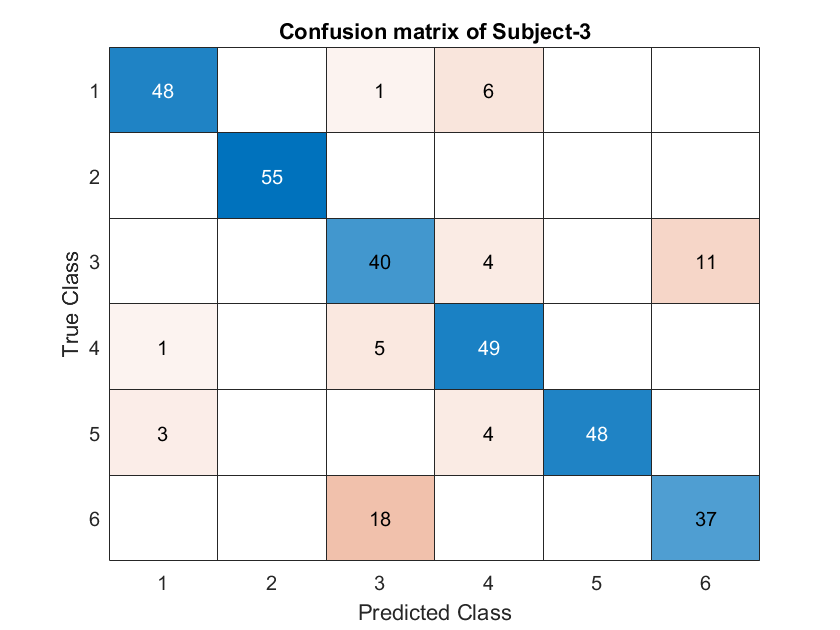

%Subject-3.
x=data(661:990,1:104);
y_pred=subject_104_3(x);
confusion=confusionmat(classes,vec2ind(y_pred'));

%Performance Metrices.
accuracy(3)=Accuracy(confusion);
precision(3,:)=Precision(confusion);
recall(3,:)=Recall(confusion);
f1(3,:)=F1_Score(precision(3,:),recall(3,:));

%Confusion Matrix.
figure;
confusionchart(classes,vec2ind(y_pred'));
title('Confusion matrix of Subject-3');

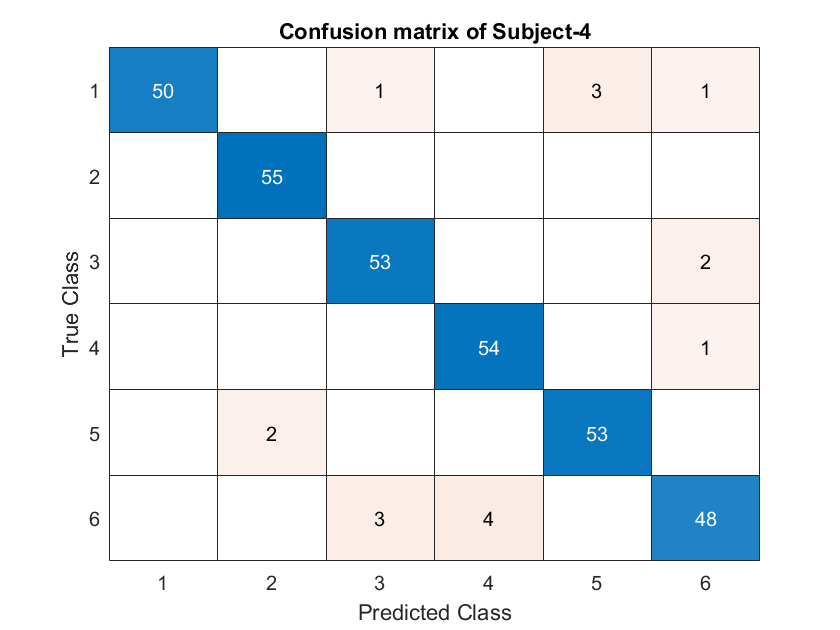

%Subject-4.
x=data(991:1320,1:104);
y_pred=subject_104_4(x);
confusion=confusionmat(classes,vec2ind(y_pred'));

%Performance Metrices.
accuracy(4)=Accuracy(confusion);
precision(4,:)=Precision(confusion);
recall(4,:)=Recall(confusion);
f1(4,:)=F1_Score(precision(4,:),recall(4,:));

%Confusion Matrix.
figure;
confusionchart(classes,vec2ind(y_pred'));
title('Confusion matrix of Subject-4');

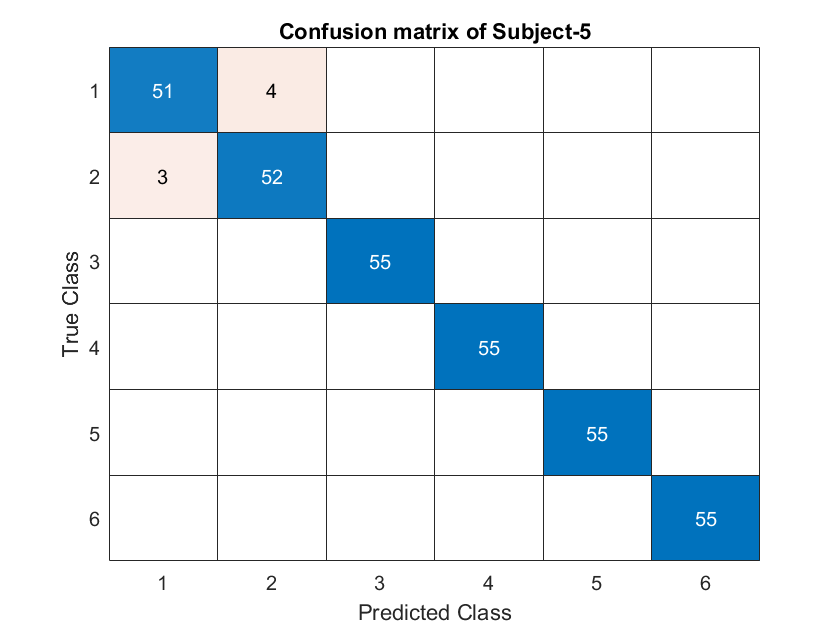

%Subject-5.
x=data(1321:1650,1:104);
y_pred=subject_104_5(x);
confusion=confusionmat(classes,vec2ind(y_pred'));

%Performance Metrices.
accuracy(5)=Accuracy(confusion);
precision(5,:)=Precision(confusion);
recall(5,:)=Recall(confusion);
f1(5,:)=F1_Score(precision(5,:),recall(5,:));

%Confusion Matrix.
figure;
confusionchart(classes,vec2ind(y_pred'));
title('Confusion matrix of Subject-5');

ticks=[1 2 3 4 5 6];
labels={'Cylindrical Grasp','Tip','Hook','Palmar','Spherical','Lateral'};

**Performance Metrices:** Accuracy, Precision, Recall, F1-Score are calculated.

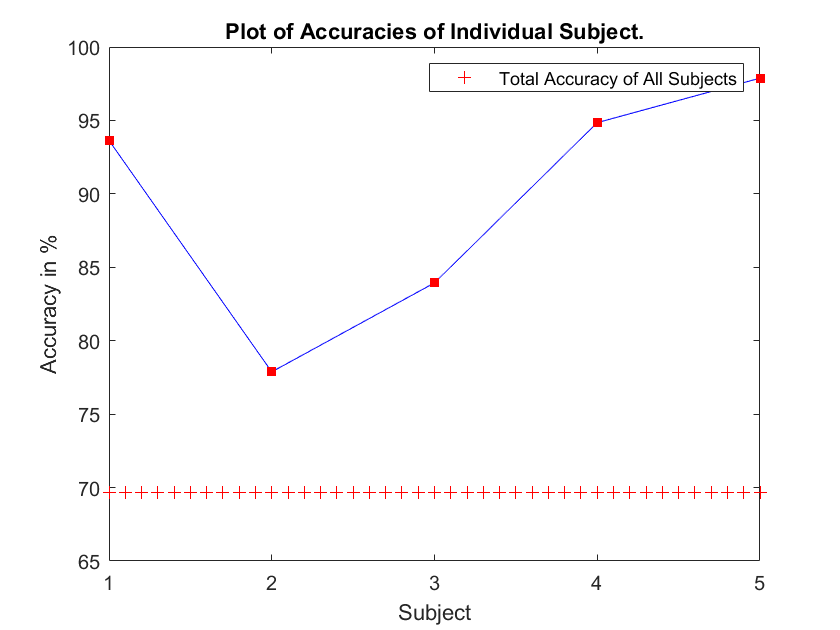

%Plotting the Performance Metrices.

figure;
plot([1:0.1:5],accuracy(6)*100,'r+');
hold on;
plot(1:5,accuracy(1:5).*100,'b');
hold on;
h=plot(1:5,accuracy(1:5).*100,'rs');
set(h,'MarkerFaceColor',[1 0 0]);
title('Plot of Accuracies of Individual Subject.');
xlabel('Subject');
ylabel('Accuracy in %');
xticks(1:5);
yticks(60:5:100);
hold off;
legend('Total Accuracy of All Subjects');

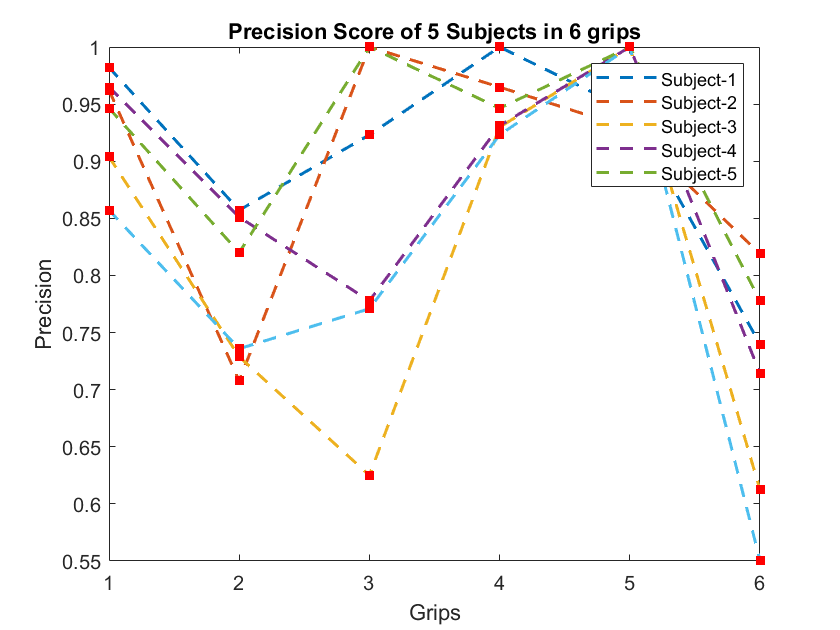

figure;
plot(precision,'--','LineWidth',1.5);
title('Precision Score of 5 Subjects in 6 grips');
xlabel('Grips');
ylabel('Precision');
hold on;
h=plot(precision,'rs');
set(h,'MarkerFaceColor',[1 0 0]);
hold off;
legend('Subject-1','Subject-2','Subject-3','Subject-4','Subject-5');

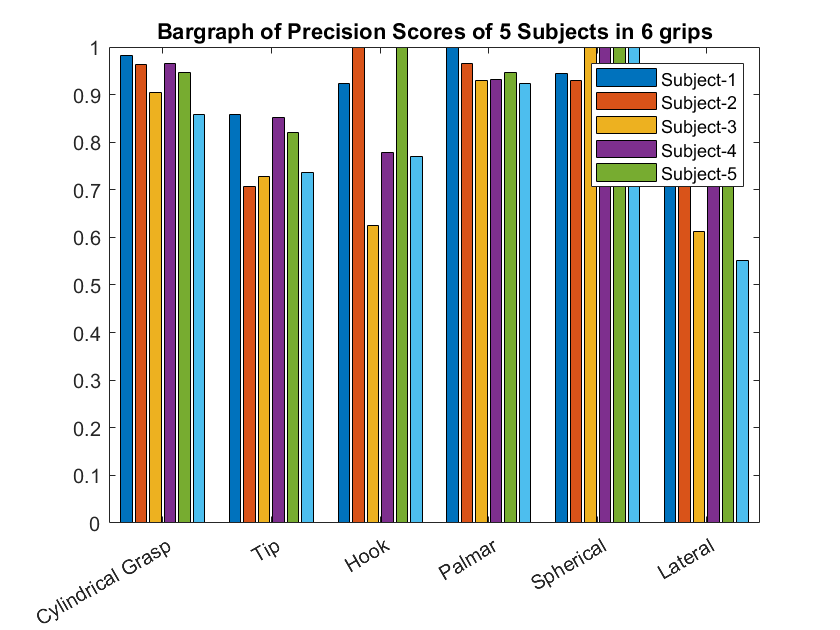

figure;
bar(precision);
title('Bargraph of Precision Scores of 5 Subjects in 6 grips');
xticks(ticks);
xticklabels(labels);
legend('Subject-1','Subject-2','Subject-3','Subject-4','Subject-5');

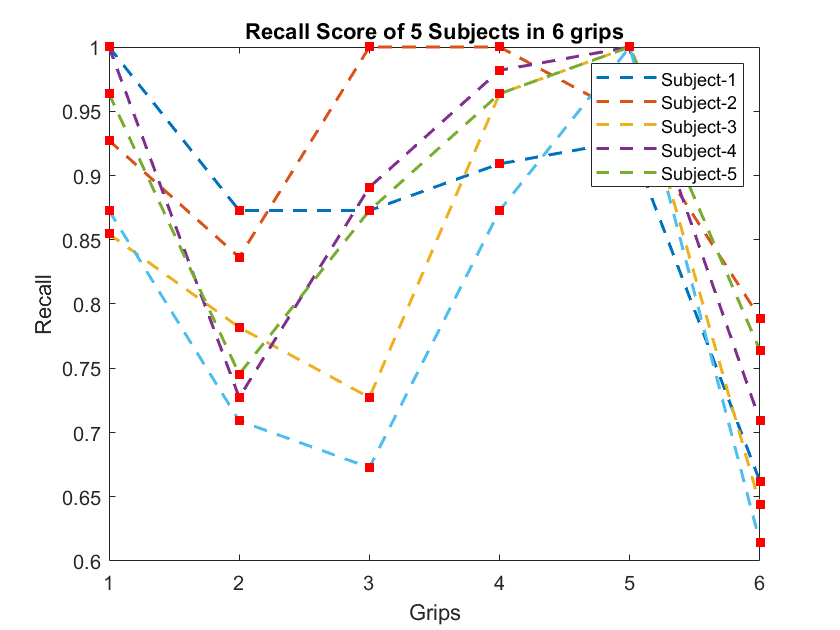

figure;
plot(recall,'--','LineWidth',1.5);
title('Recall Score of 5 Subjects in 6 grips')
xlabel('Grips');
ylabel('Recall');
hold on;
h=plot(recall,'rs');
set(h,'MarkerFaceColor',[1 0 0]);
hold off;
legend('Subject-1','Subject-2','Subject-3','Subject-4','Subject-5');

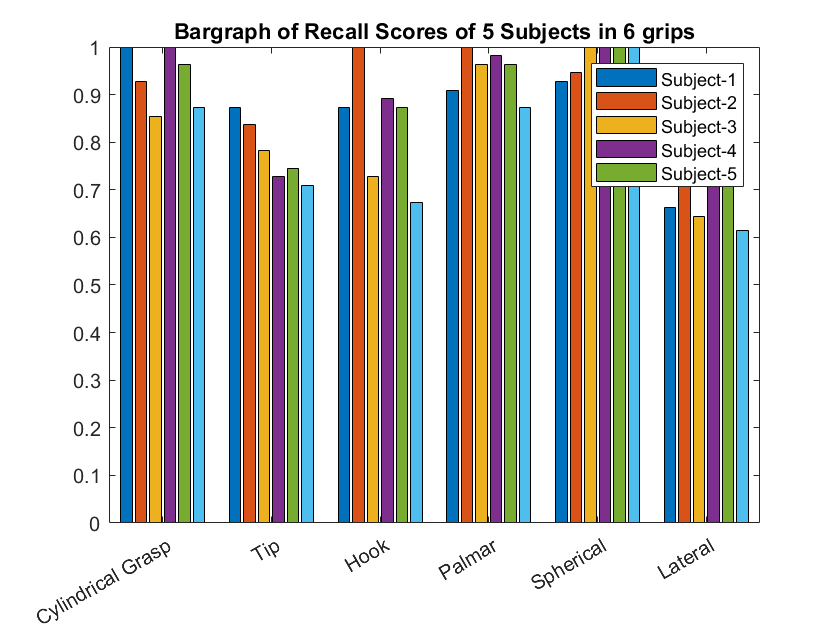


figure;
bar(recall);
title('Bargraph of Recall Scores of 5 Subjects in 6 grips');
xticks(ticks);
xticklabels(labels);
legend('Subject-1','Subject-2','Subject-3','Subject-4','Subject-5');

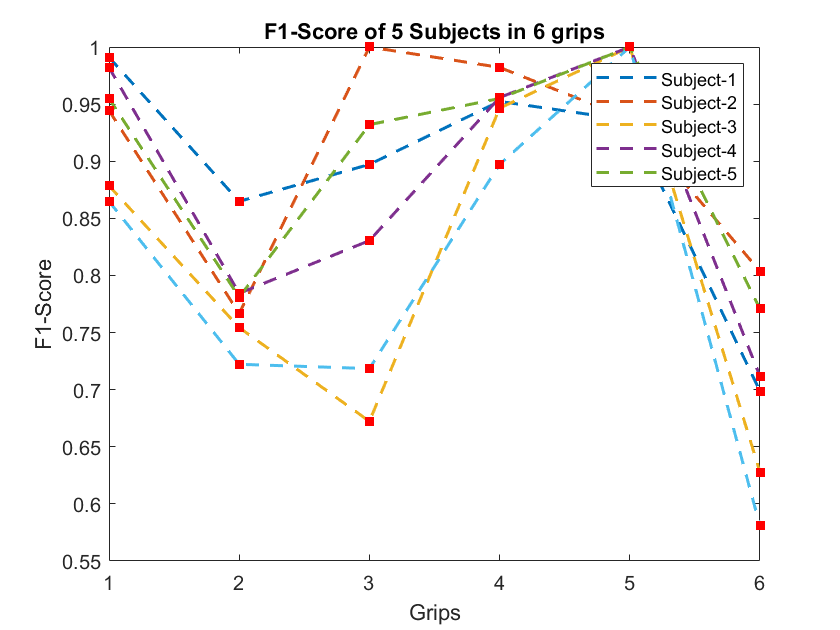

figure;
plot(f1,'--','LineWidth',1.5);
title('F1-Score of 5 Subjects in 6 grips');
xlabel('Grips');
ylabel('F1-Score');
hold on;
h=plot(f1,'rs');
set(h,'MarkerFaceColor',[1 0 0]);
hold off;
legend('Subject-1','Subject-2','Subject-3','Subject-4','Subject-5');

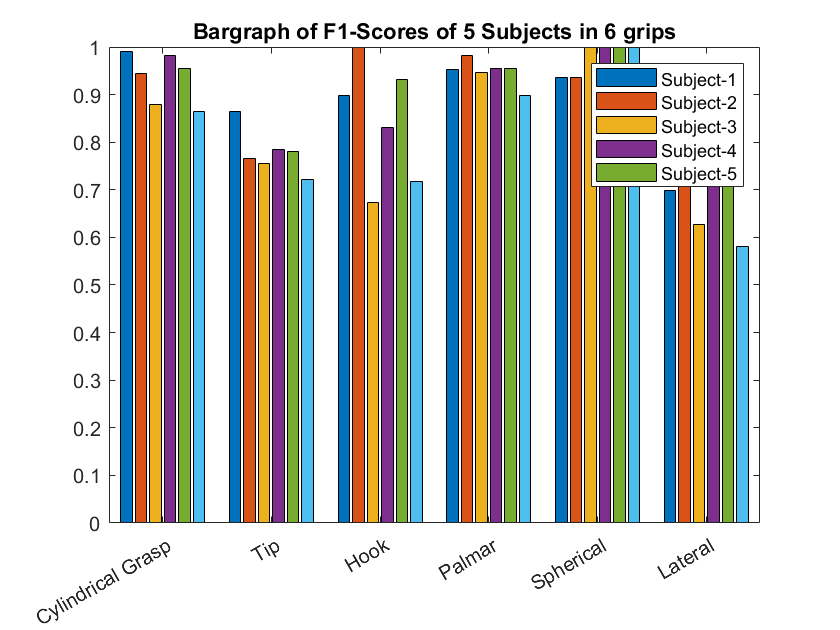


figure;
bar(f1);
title('Bargraph of F1-Scores of 5 Subjects in 6 grips');
xticks(ticks);
xticklabels(labels);
legend('Subject-1','Subject-2','Subject-3','Subject-4','Subject-5');